% Estimate maximum range of Radar Sensor  
%Operating frequency (Hz)
fc = 77.0e9;

%Transmitted power (W)
Pt = 3e-3;

%Antenna Gain (linear)
G =  10000;

%Minimum Detectable Power
Ps = 1e-10;

%RCS of a car
RCS = 100;

%Speed of light
c = 3*10^8;

%TODO: Calculate the wavelength
lambda = c/fc;

%TODO : Measure the Maximum Range a Radar can see.
R = ((Pt*G^2*lambda^2*RCS)/(Ps*(4*pi)^3))^0.25;

fprintf("Maximum radar range is : %.3f metres \n",R)

Maximum radar range is : 218.871 metres 


% Exercise2 Range Estimation 
range = 300; %m 
res = 1; %m 
c = 3*10^8; %m/s

f = [0, 1.1 , 13 , 24 ]*1e6; %MHz

% TODO : Find the Bsweep of chirp for 1 m resolution
Bsweep = c/2 * res; 

% TODO : Calculate the chirp time based on the Radar's Max Range
Tchirp = 5.5*2.2* range/c; %in general for FMCW the sweep time should be at least 5 to 6 times the 
%round trip time 

% TODO : define the frequency shifts 
calculated_range = c*Tchirp*f/(2*Bsweep); 

% Display the calculated range
disp("Objects are located in the following metre distances")

Objects are located in the following metre distances


disp(calculated_range);

         0   13.3100  157.3000  290.4000



% Doppler Velocity Calculation
clear
c = 3*10^8;         %speed of light
f = 77e9;   %frequency in Hz

% TODO : Calculate the wavelength
lambda = c/f; 
% TODO : Define the doppler shifts in Hz using the information from above 
fd = [3, -4.5, 11, -3] * 1e3; % frequency shifts in KHz 

% TODO : Calculate the velocity of the targets  fd = 2*vr/lambda
vr = fd * lambda /2; 

% TODO: Display results
disp("The velocities of the targets in m/s are : ")

The velocities of the targets in m/s are : 


disp(vr)

    5.8442   -8.7662   21.4286   -5.8442



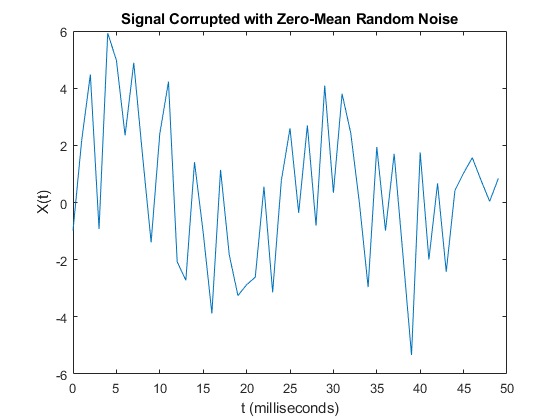

% Fourier transform 
Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector

% TODO: Form a signal containing a 77 Hz sinusoid of amplitude 0.7 and a 43Hz sinusoid of amplitude 2.
S = 0.7* sin(2*pi*77*t) + 2*sin(2*pi*43*t);

% Corrupt the signal with noise 
X = S + 2*randn(size(t));

% Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal X(t). 
plot(1000*t(1:50) ,X(1:50))
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

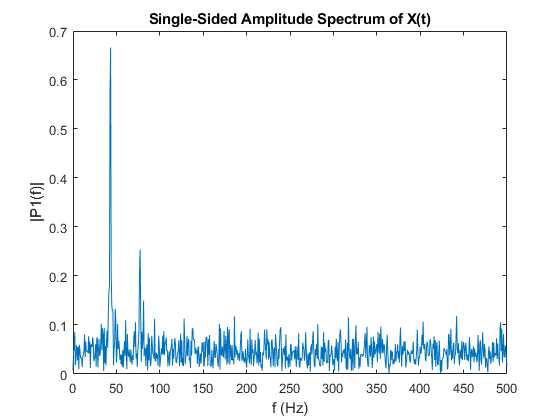


% TODO : Compute the Fourier transform of the signal. 
P2 = abs(fft((X))/L);
% TODO : Compute the two-sided spectrum P2. Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.
P1 = P2(1:(L/2)+1);

% Plotting
f = Fs*(0:(L/2))/L; %only show positive part of the plot as negative one is not needed
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

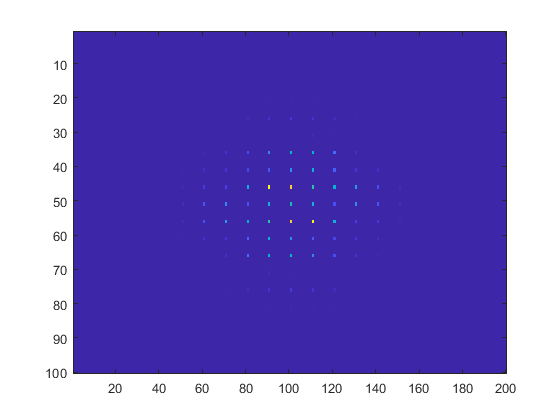

%velocity estimation 
% 2-D Transform
% The 2-D Fourier transform is useful for processing 2-D signals and other 2-D data such as images.
% Create and plot 2-D data with repeated blocks.

P = peaks(20);
X = repmat(P,[5 10]);
Y = fft2(X);
imagesc(abs(fftshift(Y)))

% TODO : Compute the 2-D Fourier transform of the data.  
% Shift the zero-frequency component to the center of the output, and 
% plot the resulting 100-by-200 matrix, which is the same size as X.
